insetpatch = patchMicrostripInsetfed

insetpatch =   patchMicrostripInsetfed with properties:

               Length: 0.0300
                Width: 0.0290
               Height: 0.0013
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0300 0]
       StripLineWidth: 1.0000e-03
          NotchLength: 0.0080
           NotchWidth: 0.0030
    GroundPlaneLength: 0.0600
     GroundPlaneWidth: 0.0600
            Conductor: [1×1 metal]
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


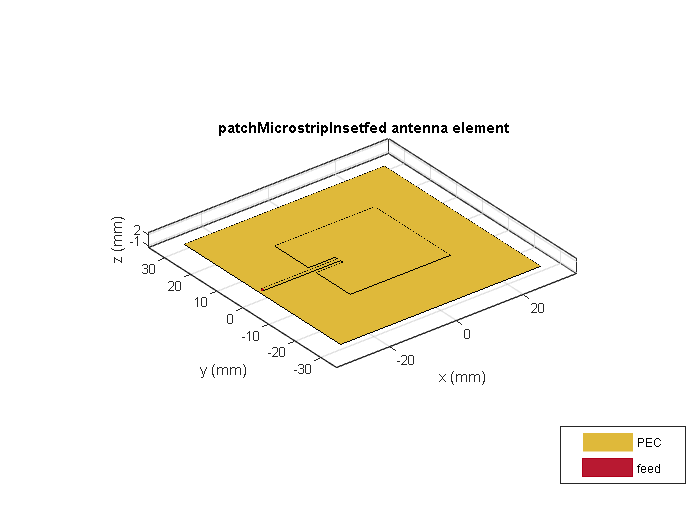

show(insetpatch)

pAI = design(patchMicrostripInsetfed,6.5e9,ForAI=true)

pAI =   AIAntenna with properties:

   Antenna Info
               AntennaType: 'patchMicrostripInsetfed'
    InitialDesignFrequency: 6.5000e+09

   Tunable Parameters
                    Length: 0.0208
                     Width: 0.0208
                    Height: 0.0012
            StripLineWidth: 0.0013
               NotchLength: 0.0031
                NotchWidth: 0.0023

Show read-only properties


pAI.NotchLength = 0.0034;
pAI.NotchWidth = 0.0020;
resonantFrequency(pAI)

ans = 6.5342e+09